# EXERCISE #1 : Build the Simplest WLAN Network

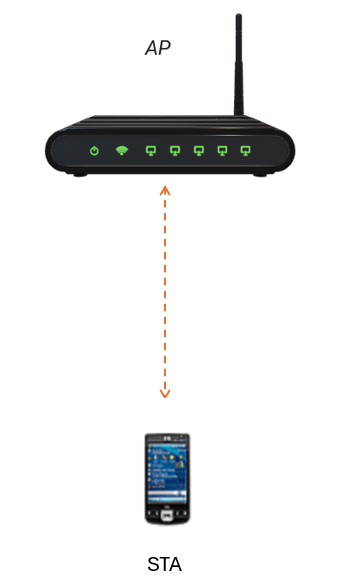

WLAN Network with one AP and one STA 

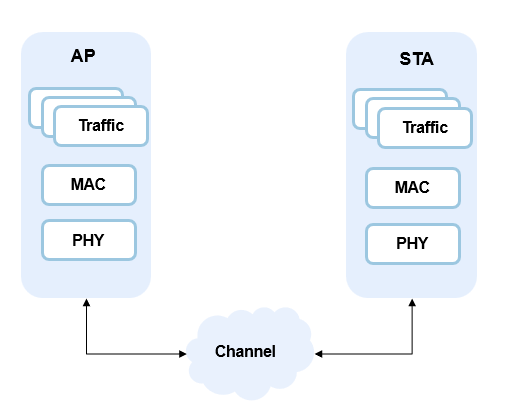

Modeled Blocks 

#### In this exercise, You will learn how to  

- Model a simple WLAN network and explore the WLAN network modeling workflow. 

- Model the physical (PHY), MAC, and application layers for WLAN nodes, along with the wireless channel. 

- Visualize WLAN MAC layer state transitions, capture statistics, and measure network KPIs. 

- Perform cleanup by closing previously opened windows and figures. 

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs); 

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

rng(1,"twister");
TU              = 1024e-6; % Time Unit(TU) in WLAN is 1024 us 
simulationTime  = 100*TU;  % Simulation time is set to 100*TU 
networkSimulator = wirelessNetworkSimulator.init;
networkViewerObj = wirelessNetworkViewer(CanvasSize=[50 50 0]);

# Task 1/8 Configure a WLAN Access Point (AP)

**Description of the task**

Configure WLAN AP

- Operates in the 2.4 GHz band with 20 MHz channel bandwidth (Channel 7) 

- Transmits a beacon every 10 TU (10.24 ms) 

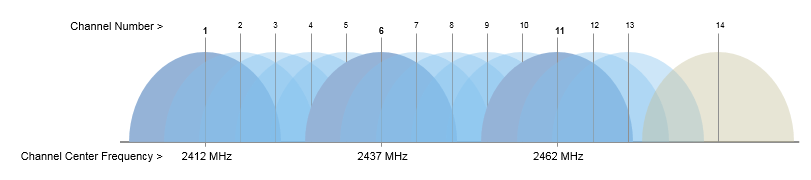

**Instructions to complete the task**

Use wlanDeviceConfig() function to configure the AP

Write configuration in a variable named "APCfg"

Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

-     "Mode","AP"

-     "TransmissionFormat", transmissionFormat

-     "BandAndChannel",[band, channel]

-     "ChannelBandwidth",bandwidth

-      "BeaconInterval", 10

-      "MCS",mcs

transmissionFormat = "HE-SU";
mcs = 0;
band        = 2.4;
channel     = 7;
bandwidth   = 20e6;

% <enter code below>
% APCfg = 

# Task 2/8: Create a WLAN Access Point (AP)

**Description of the task**

Configure the abstraction level of the MAC and PHY, and set the position of the access point.

**PHY Options**

- **Full PHY (IQ samples)**

- Supports waveform generation and decoding 

- **Abstracted PHY**

- Uses PER tables based on the 802.11ax evaluation methodology 

- Enables PHY abstraction for system-level simulation 

- **Pass-through PHY (MAC calibration)**

- No PHY is modeled 

- Interfered packets are dropped 

**MAC Options**

- **Full MAC**

- EDCA MAC with full MAC frame generation 

- **Abstracted MAC**

- EDCA MAC without MAC frame generation 

**Note / Implication**

- Use **Full MAC** if you want to capture WLAN packets in PCAP files and analyze them in Wireshark.

- All nodes on the network must have same MAC and PHY abstraction

- You can't set Abstracted MAC and full PHY

**Instructions to complete the task**

Use wlanNode() function to instantiate the AP using the configuration you have just created

Hint: Type "doc wlanNode" in the MATLAB Command Window, and see the "Syntax" section.

Name the variable "AP"

Pass the following as arguments 

- "DeviceConfig",APCfg

- "Position", AP_pos

- Name="AP"

- "PHYModel",phymodel

- "MACModel",macmodel

macmodel = "full-mac";
phymodel = "full-phy";
AP_pos= [0, 0, 0];

% <enter code below>
% AP = 

#### Visualize the Access Point in the Network Viewer 

Add node to the network viewer for visualization 

addNodes(networkViewerObj,AP,Type="AP");

# Task 3/8: Configure a WLAN Station (STA)

**Description of the task**

Configure WLAN STA

- Operates in the 2.4 GHz band with 20 MHz channel bandwidth (Channel 7) 

**Instructions to complete the task**

Use wlanDeviceConfig() function to configure the STA

Write configuration in a variable named "STACfg"

Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- "Mode","STA"

-  "TransmissionFormat",transmissionFormat

-  "BandAndChannel",[band, channel]

-  "ChannelBandwidth",bandwidth

- "MCS",mcs

% <enter code below>
% STACfg = 

# Task 4/8: Create a WLAN Station (STA)

**Description of the task**

Configure the abstraction level of the MAC and PHY, and set the position of the access point.

**PHY Options**

- **Full PHY (IQ samples)**

- Supports waveform generation and decoding 

- **Abstracted PHY**

- Uses PER tables based on the 802.11ax evaluation methodology 

- Enables PHY abstraction for system-level simulation 

- **Pass-through PHY (MAC calibration)**

- No PHY is modeled 

- Interfered packets are dropped 

**MAC Options**

- **Full MAC**

- EDCA MAC with full MAC frame generation 

- **Abstracted MAC**

- EDCA MAC without MAC frame generation 

**Instructions to complete the task**

Use wlanNode() function to instantiate the AP using the configuration you have just created

Hint: Type "doc wlanNode" in the MATLAB Command Window, and see the "Syntax" section.

Name the variable "STA"

Pass the following as arguments 

- "DeviceConfig",STACfg

- "Position", STA_pos

- Name="STA"

- "PHYModel",phymodel

- "MACModel",macmodel

STA_pos= [5, 0, 0];

% <enter code below>
% STA = 

#### Visualize the station in the Network Viewer 

Add node to the network viewer for visualization 

addNodes(networkViewerObj,STA,Type="STA");

# Task 5/8: Associate the AP with the STA to create a Basic Service Set (BSS).

**Instructions to complete the task**

Use associateStations() function to define associations between AP's and STA's

Hint: In the command line type `doc wlannode.associatestations `and and see the "Syntax" section.

Pass the following as arguments 

- AP

- STA

- "FullBufferTraffic", trafficType

**Notes:**

Create a Basic Service Set (BSS) and configure full-buffer traffic.

- Off: Only beacon frames are transmitted (no data traffic) 

- Bidirectional: Traffic flows in both uplink (UL) and downlink (DL) 

- DL (Downlink): Traffic from AP to stations 

- UL (Uplink): Traffic from stations to AP

TrafficType = "off";

% <enter code below>


#### **Add nodes to the network **

Calling addNodes adds nodes to the simulator

wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)

**Enable PCAP capture**

The wlanPCAPWriter saves generated and received WLAN MAC packets to a PCAP or PCAPNG file.

capturePacketsObj =wlanPCAPWriter(Node=wlanNodes, RadiotapPresent=1);

#### Enable capture of IQ samples

Use the `wirelessIQLogger`  to log in-phase and quadrature (IQ) samples from wireless nodes in a wireless network simulation.

enableIQCapture = false;
if enableIQCapture
    iqSampleObj = wirelessIQLogger(wlanNodes);
end

#### Enable packet visualization

- Use the **wirelessTrafficViewer** object to monitor wireless nodes 

- View node state transitions over time 

- See channel occupancy for each node 

- Visualize packet transmissions over time 

viewerObj = wirelessTrafficViewer;
addNodes(viewerObj,wlanNodes);

#### Enable node performance visualization 

perfViewerObj = helperPerformanceViewer(wlanNodes,simulationTime);

# Task 6/8: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use run() function to run the model    

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

% <enter code below>


#### Plot node performance (Throughput , Packet Loss, and Latency) 

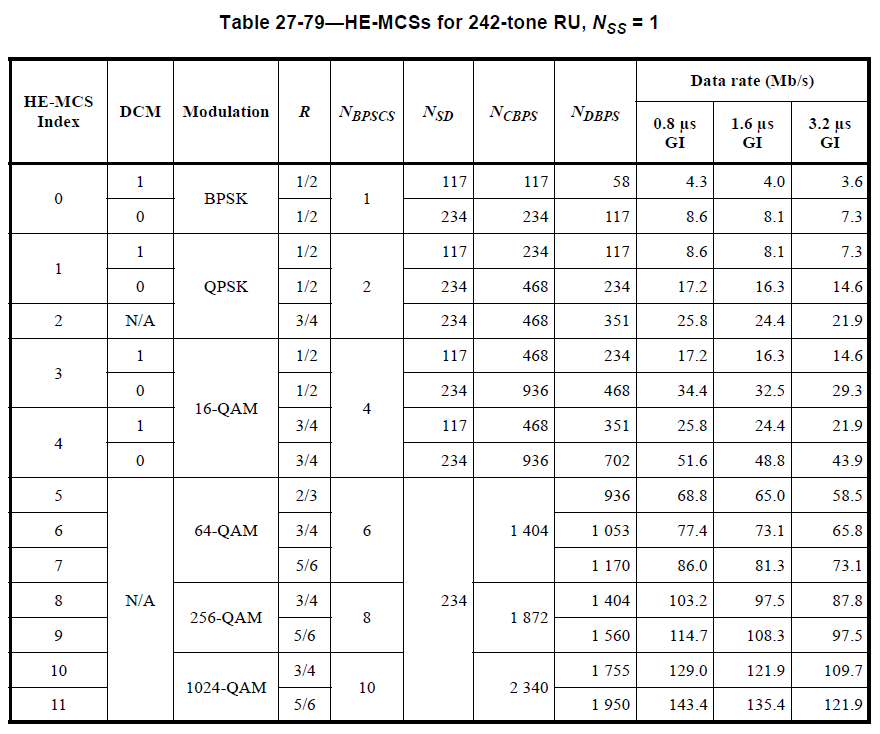

plotNetworkStats(perfViewerObj);

# Task 7/8: Capture Statistics at AP

Use statistics() function to get statistics for AP 

Create a variable name APStatistics 

Hint:  type `doc wlannode.statistics` and see the "Syntax" section.

Note : use the following values as arguments 

- AP

% <enter code below>
% APStatistics =

Print statistics for APP, MAC, and PHY layers at the AP

APStatistics.App
APStatistics.MAC
APStatistics.PHY

# Task 8/8: Capture Statistics at STA

Use statistics() function to get statistics (for APP, MAC, PHY layers) for AP 

Create a variable name `STAStatistics` 

Hint:  type `doc wlannode.statistics` and see the "Syntax" section.

Note : use the following values as arguments 

- STA

% <enter code below>
% STAStatistics = 

Print statistics for APP, MAC, and PHY layers at the STA

STAStatistics.PHY
STAStatistics.MAC
STAStatistics.App

#### IQ sample visualization

enableIQVisualization = false; 
if enableIQVisualization
    fileName = iqSampleObj(1).FileName;
    iqData = load(fileName);
    signalAnalyzer(iqData.Waveform,SampleRate=iqData.Fs);
end
delete(capturePacketsObj);

Copyright 2025-2026 The MathWorks, Inc